clc;
clear;
close all;

## Esercizio 1

generi in modo pseudo-random un numero n intero tra 10 e 50 e verifichi che sia divisibile per 3. Stabilito che il numero inserito soddisfa i requisiti richiesti, si costruisca e si visualizzi la matrice D di dimensione n × n fatta nel seguente modo

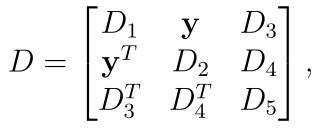

dove,

• D1 ∈ $R^{\frac{n}{3}\times \frac{n}{3}}$ contiene tutti valori uguali a 1;

• y è un vettore colonna di lunghezza $n/3$ che contiene tutti valori uguali a 0;

• D2 contiene tutti valori uguali a 2;

• D3 contiene tutti valori uguali a 3;

• D4 contiene tutti valori uguali a 4;

• D5 contiene tutti valori uguali a 5.

Dedurre le dimensioni delle matrici D2 , D3 , D4 e D5 .

Se il numero generato n non dovesse verificare le condizioni richieste, dovrà esserne

richiesto uno nuovo fino a quando non si ottiene un numero consentito.

n = 1;
while(mod(n, 3) ~= 0)
    n = randi([10 50], 1);
end
n
D1 = ones(n/3);
y = zeros(n/3, 1);
yT = y';

D3 = 3 * ones(n/3, n-(n/3)-1);
D3T = D3';
D2 = 2 * ones(n/3);
D4 = 4 * ones(n/3);
D4T = D4';
D5 = 5 * ones(n/3);


D11 = [D1 y D3];
D22 = [yT; D3T];
D33 = [D2 D4; D4T D5];

D = [D11; D22 D33]

clc;
clear;
close all;

## Esercizio 2

crei la matrice dei coefficienti di un sistema lineare Ax = b, con A di dimensione da 10 a 100 con passo 10, contenente numeri pseudo-casuali reali compresi tra −5 e 10. Imporre una soluzione nota x di elementi uguali a −5, calcolare il corrispondente termine noto b e trovare la soluzione x1 tramite l’algoritmo di Gauss con pivoting. Infine, calcolare e visualizzare in un sistema di assi cartesiani l’errore relativo tra la soluzione vera x e quella ottenuta x1 in corrispondenza della dimensione. Il grafico dovrà essere corredato da un titolo e una legenda.

La funzione [U,c] = gauss_piv(A,b) dovrà essere allegata alla fine dello script.

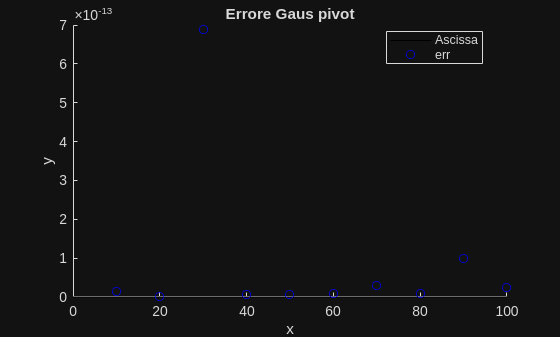

iMin = -5;
iMax = 10;
k = 1;

for i = 10 : 10 : 100
    A = (iMax-iMin) * rand(i) + iMin;
    x = -5 * ones(i, 1);
    b = A*x;
    
    [U, b2] = gauss_piv(A, b);
    x1 = U\b2;

    errRel(k) = norm(x - x1) / norm(x1);
    k = k+1;
end

asc = linspace(0, 100, 100);
hs = 10 : 10 : 100;

figure;
hold on;
title("Errore Gaus pivot");
xlabel("x")
ylabel("y");

plot(asc, zeros(size(asc)), "-k", "DisplayName", "Ascissa");
plot(hs, errRel, "ob", "DisplayName", "err");

legend("Location","best");
hold off;

clc;
clear;
close all;

## Esercizio 3

implementi un test per l’approssimazione della radice positiva dell’equazione nonlineare

utilizzando il metodo delle corde, partendo da x0 = 1 e m = f ′ (x0 ), e il metodo di Newton, partendo da x0 = 1. Per entrambi i metodi, impostare una tolleranza τ = 10e−5 e un numero massimo di iterazioni kmax = 100. Infine si stampi, sullo stesso sistema di assi cartesiani, il grafico della funzione f (x) e le due approssimazioni ottenute. Il grafico dovrà essere corredato da un titolo e una legenda.

Le due funzioni

• [xn ,kn ] = newton(f,fder,x0 ,τ ,kmax)

• [xb ,kb ] = corde(f,m,x0 ,τ ,kmax)

dovranno essere allegate alla fine dello script.

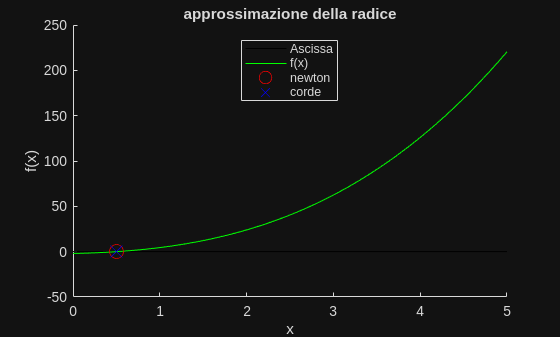

tau = 10e-5;
kmax = 100;
x0 = 1;

f = @(x) (x - 0.5) .* (x + 2).^2;
fder = @(x) (x + 2).^2 + (x-0.5).*(x+2);

m = fder(x0);

x = linspace(0, 5);

[xn, kn] = newton(f, fder, x0, tau, kmax);
[xb, kb] = corde(f, m, x0, tau, kmax);

figure;
hold on;
title("approssimazione della radice");
xlabel("x");
ylabel("f(x)");

plot(x, zeros(size(x)), "-k", "DisplayName", "Ascissa");
plot(x, f(x), "-g", "DisplayName", "f(x)");
plot(xn, f(xn), "or", "DisplayName", "newton", "MarkerSize", 10);
plot(xb, f(xb), "xb", "DisplayName", "corde", "MarkerSize", 12);

legend("Location", "best");
hold off;

function [U, b2] = gauss_piv(A, b)

    % gauss_p: funzione che calcola la riduzione di Gauss con pivoting e 
    % prende in ingresso la matrice A e il vettore di termini noti b.
    % [U, b2] = gauss_p(A, b) restituisce la riduzione di Gauss, non i 
    % termini noti

    % Controlli preliminari sulle dimensioni di matrice, vettore e sul
    % determinante di A
    [m, n] = size(A);
    if m ~= n
        error("la matrice deve essere quadrata");
    end
    if size(b, 1) ~= n || size(b, 2) ~= 1
        error("b deve essere un vettore colonna con n righe");
    end
    if abs(det(A)) < 1e-10
        error("La matrice A è singolare");
    end


    for k = 1 : n-1

        [~, pos] = max(abs(A(k:n,k))); % Prendo le righe da k in giù nella colonna corrente
        % In pratica scarto il valore e prendo solo la posizione

        % Però ho il valore nel vettore che sto considerando, non della
        % matrice originale:
        l = pos + k - 1;

        % E poi scambio le righe:
        % Prendo la riga k E la riga l
        A([k l], :) = A([l k], :);
        b([k l]) = b([l k]);


        for i = k+1 : n
            m = A(i, k) / A(k, k);

            % Calcolo della nuova riga per ottenere una triangolare
            % inferiore
            A(i, :) = A(i, :) - m * A(k, :);

            b(i) = b(i) - m * b(k);
        end
    end

    % Assegno il valore corretto alle matrici da restituire
    U = A;
    b2 = b;
end

function [xn, kn] = newton(f, fder, x0, tau, kmax)
    kn = 1;
    xn = -1;
    f1 = fder(x0);

    if(abs(f(x0)) < tau)
        xn = x0;
        return;
    end

    while(kn < kmax && abs(f(xn)) >= tau)
        
        if(abs(f1) < tau)
            error("Cambia x0");
        end

        xn = x0 - f(x0) / f1;
        
        x0 = xn;
        f1 = fder(x0);

        kn = kn + 1;
    end
end

function [x, k] = corde(fun, m, x0, tol, kmax)
    
    k = 0;
    if (abs(fun(x0)) < tol)
        x = x0;
        return
    end

    x_new = x0;
    flag = 1;
    while flag
        k = k + 1;
        xk = x_new;
        fk = fun(xk);

        x_new = xk - fk / m;

        
        flag = (abs(x_new - xk) > abs(xk) * tol) && (k < kmax) && abs(fun(x_new)) > tol;

    end

    if k >= kmax
        warning("Raggiunto kmax");
        x = inf;
    else
        x = x_new;
    end

end
